# Feedforward neural network

BE CAREFUL, THIS SCRIPT CAN OVERWRITE FILES

buffer_train = struct with fields:
    X: [22×10000 double]
    Y: [5×10000 double]

buffer_validation = struct with fields:
    X: [22×1000 double]
    Y: [5×1000 double]

Nsamples = 11000

Ninputs = 22

Noutputs = 5

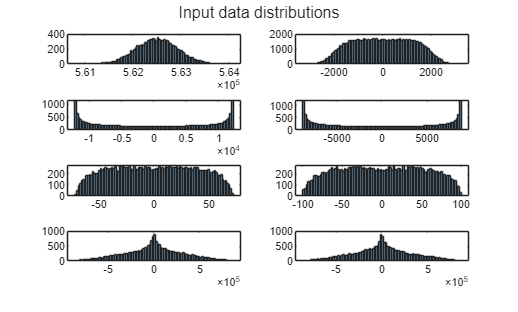

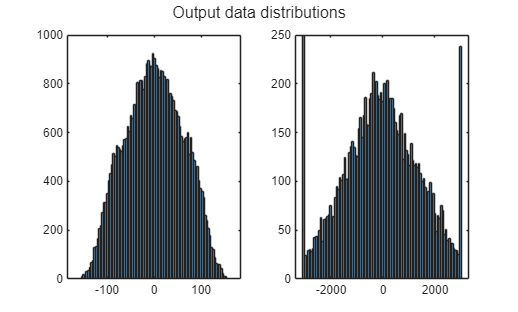

ans = 55.7759

ie_max = 167.1361

ix_max = 71.4286

iy_max = 100

is_max = 114.2857

vo_max = 3000

vB_max = 12000

VCdiff = 0.0020

C = 0.0050

vc_mean_ref = 15000

Xmax = 1.0e+05 *

    5.6250
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.0225
    0.1212
    0.1212
    0.0866
    0.0866
    0.0007


Ymax = 1.0e+03 *

    0.2286
    0.2286
    0.2286
    0.2286
    3.0000


ans =           22       11000


ans =            5       11000


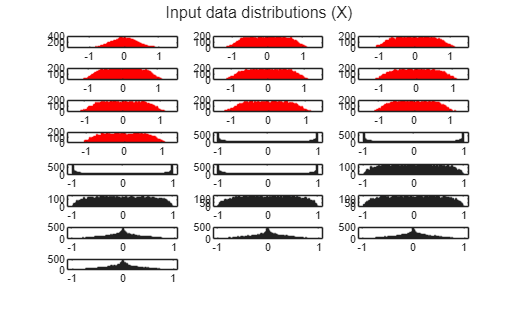

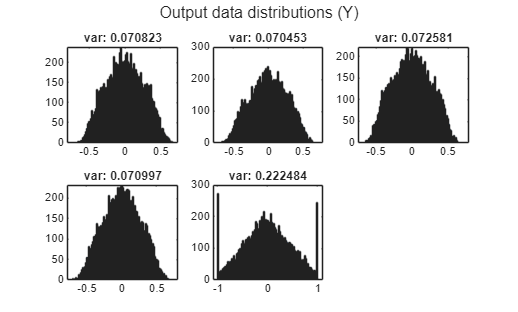

run('DataPreparation.mlx');

## Architecture

argsFFNN                  = struct();
argsFFNN.Ninputs          = Ninputs;
argsFFNN.Noutputs         = Noutputs;
% argsFFNN.Nlayers          = 1;
% argsFFNN.Nneurons         = 5*Ninputs;
argsFFNN.Nlayers          = 1;
argsFFNN.Nneurons         = 3*Ninputs;
argsFFNN.HiddenActivation = 'relu'; % relu, tanh, sigmoid
argsFFNN.OutputActivation = 'tanh';
argsFFNN.Dropout          = 0;
argsFFNN.WinitFcn         = 'glorot';
argsFFNN.BinitFcn         = 'glorot';
argsFFNN.BatchNorm        = true;
argsFFNN.TrainBias        = true;

net = FFNNgenerator(argsFFNN)

net =   dlnetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'layer'}
    Initialized: 1
  View summary with summary.

Add projection layer

% layers = layerGraph(net);
% concatLayer = concatenationLayer(1, 2, 'Name', 'concat');
% projLayer = HardNetProjection('cimmino_max', A, N, C, is_max, Xmax, Ymax, 'projection');
% layers = addLayers(layers, concatLayer);
% layers = addLayers(layers, projLayer);
% layers = connectLayers(layers, net.Layers(end).Name, 'concat/in1');
% layers = connectLayers(layers, net.InputNames{1}, 'concat/in2');
% layers = connectLayers(layers, 'concat', 'projection');
% net = dlnetwork(layers)

## Training

output_variance = var(extractdata(dlY_tr), 0, 2);
var_e = mean(output_variance(1:4));
var_o = output_variance(5);
ErrorWeights = [ones(4, 1); var_e/var_o*0+1]

ErrorWeights =      1
     1
     1
     1
     1



argsFFNNtrain                    = struct();
argsFFNNtrain.net                = net;
argsFFNNtrain.X_tr               = dlX_tr;
argsFFNNtrain.Y_tr               = dlY_tr;
argsFFNNtrain.dsXY_tr            = dsXY_tr;
argsFFNNtrain.X_val              = dlX_val;
argsFFNNtrain.Y_val              = dlY_val;
argsFFNNtrain.Plots              = 'training-progress'

argsFFNNtrain = struct with fields:
        net: [1×1 dlnetwork]
       X_tr: [22×10000 dlarray]
       Y_tr: [5×10000 dlarray]
    dsXY_tr: [1×1 matlab.io.datastore.CombinedDatastore]
      X_val: [22×1000 dlarray]
      Y_val: [5×1000 dlarray]
      Plots: 'training-progress'

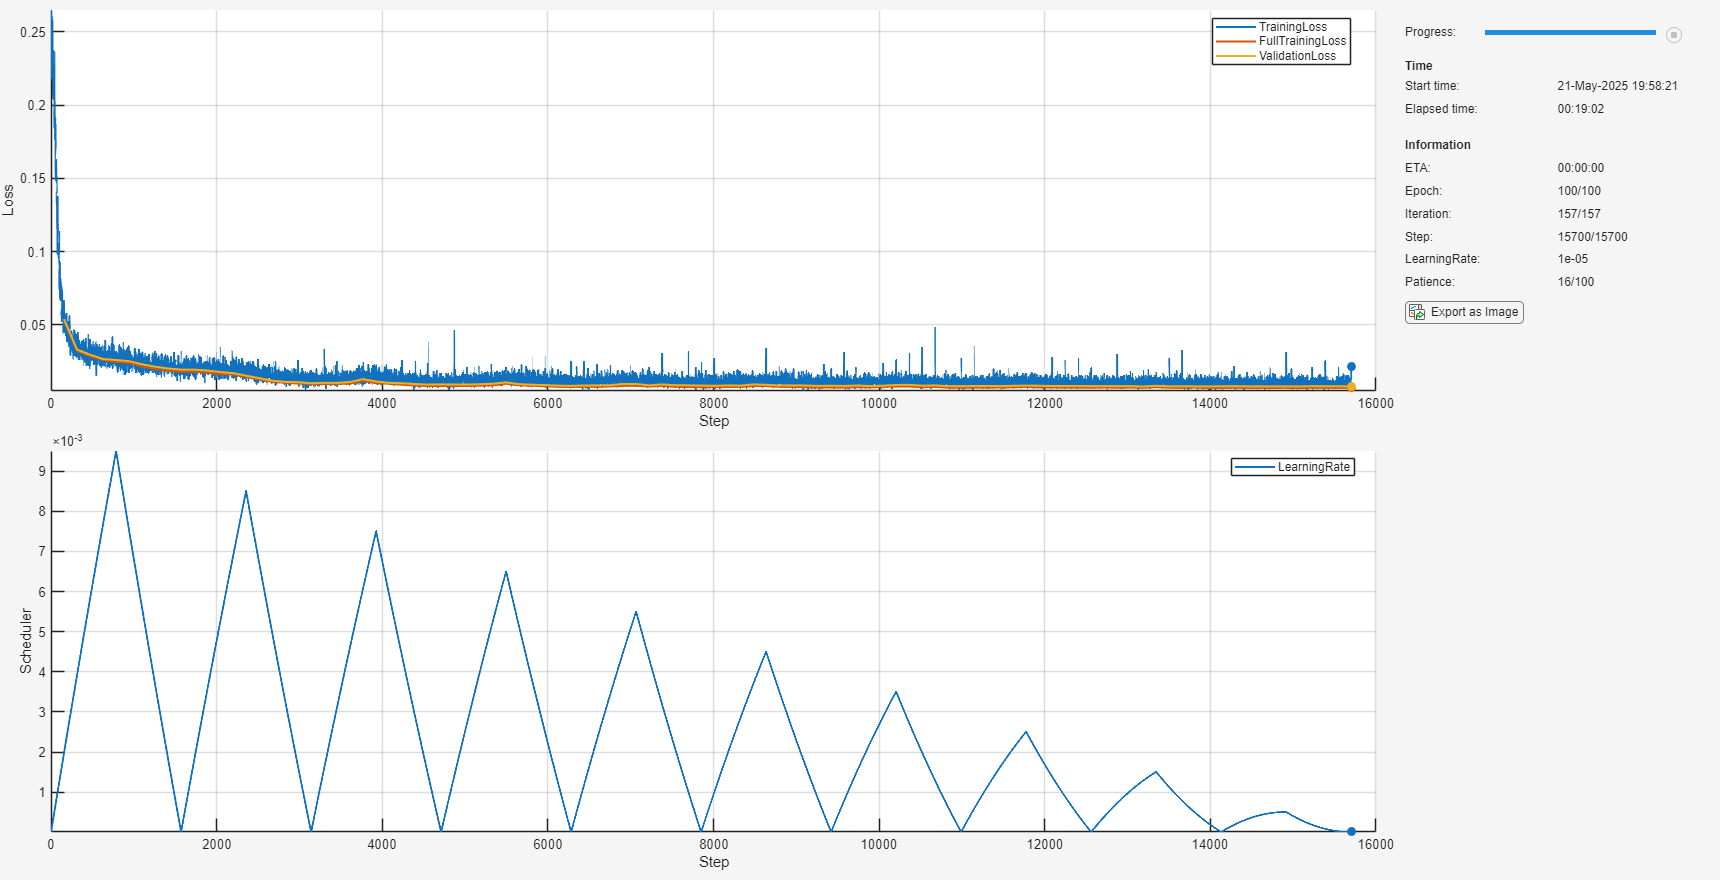

net =   dlnetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     Learnables: [6×3 table]
          State: [2×3 table]
     InputNames: {'input'}
    OutputNames: {'layer'}
    Initialized: 1
  View summary with summary.

history = 1×100 struct array with fields:
    net
    train_loss
    val_loss

argsFFNNtrain.Verbose            = false;
argsFFNNtrain.HuberThreshold     = 1;
argsFFNNtrain.ErrorWeights       = ErrorWeights;
argsFFNNtrain.LearnRateScheduler = "cyclic"; % test, exponential, cyclic, super-convergence
argsFFNNtrain.InitialLearnRate   = 1e-2;
argsFFNNtrain.FinalLearnRate     = 1e-5;
argsFFNNtrain.MinLearnRate       = 1e-5;
argsFFNNtrain.MaxLearnRate       = 1e-2;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 512;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 128;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 200;
% argsFFNNtrain.MiniBatchSize      = 256;
% argsFFNNtrain.ValidationPatience = 200;
% argsFFNNtrain.MaxEpochs          = 500;
% argsFFNNtrain.MiniBatchSize      = 1024;
% argsFFNNtrain.ValidationPatience = 500;
% argsFFNNtrain.MaxEpochs          = 1000;
% argsFFNNtrain.MiniBatchSize      = 64;
% argsFFNNtrain.ValidationPatience = 1000;
argsFFNNtrain.MaxEpochs          = 100;
argsFFNNtrain.MiniBatchSize      = 64;
argsFFNNtrain.ValidationPatience = 100;

[net, history] = FFNNtrain(argsFFNNtrain, 'custom')


save('ImitationLearning\ActualArchitecture\Results.mat', 'net', 'history');

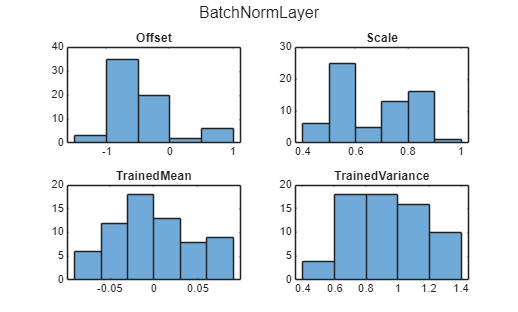

figure
subplot(2, 2, 1)
histogram(net.Layers(3).Offset)
title('Offset')
subplot(2, 2, 2)
histogram(net.Layers(3).Scale)
title('Scale')
subplot(2, 2, 3)
histogram(net.Layers(3).TrainedMean)
title('TrainedMean')
subplot(2, 2, 4)
histogram(net.Layers(3).TrainedVariance)
title('TrainedVariance')
sgtitle('BatchNormLayer')

## Summary

trainPerformance = dlfeval(@FFNNLoss, net, dlX_tr, dlY_tr, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);
valPerformance   = dlfeval(@FFNNLoss, net, dlX_val, dlY_val, 'validation', argsFFNNtrain.HuberThreshold, argsFFNNtrain.ErrorWeights);

disp(['Rendimiento en el conjunto de entrenamiento: ', num2str(trainPerformance)]);

Rendimiento en el conjunto de entrenamiento: 0.0071279


disp(['Rendimiento en el conjunto de validación: ', num2str(valPerformance)]);

Rendimiento en el conjunto de validación: 0.0079819


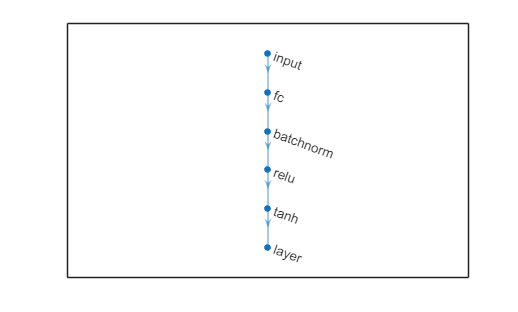


figure
plot(net)

analyzeNetwork(net);
summary(net)

   Initialized: true
   Number of learnables: 1.9k
   Inputs:
      1   'input'   22 features


# Performance analysis

## Error histogram

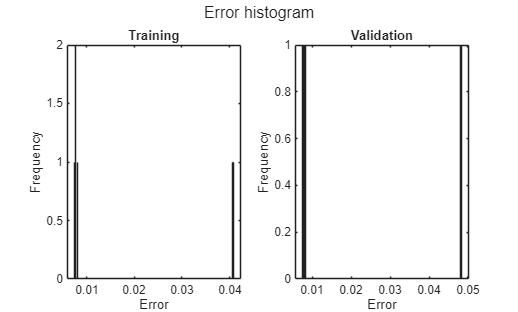

Y_tr_pred = extractdata(net.predict(dlX_tr));
Y_val_pred = extractdata(net.predict(dlX_val));

figure
subplot(1, 2, 1)
histogram(mean((Y_tr_pred - Y_tr).^2, 2), 1000)
title("Training")
xlabel("Error");
ylabel("Frequency")

subplot(1, 2, 2)
histogram(mean((Y_val_pred - Y_val).^2, 2), 1000)
title("Validation")
xlabel("Error");
ylabel("Frequency")

sgtitle('Error histogram');

## Regression

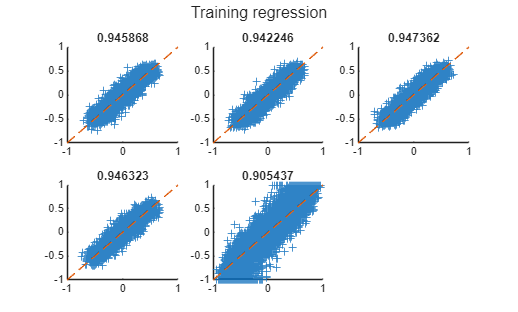

% xlabel("Predicted")
% ylabel("Actual")
% title("Correlation")

figure
title("Training")
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_tr_pred(1, :), Y_tr(1, :), "+")
title(corr(Y_tr_pred(1, :)', Y_tr(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_tr_pred(idx, :), Y_tr(idx, :), "+")
    title(corr(Y_tr_pred(idx, :)', Y_tr(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Training regression');

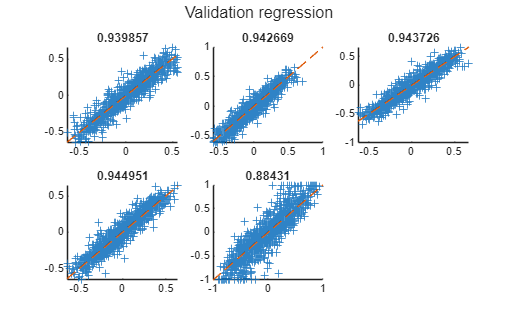


figure
subplot(ceil(Noutputs/3), 3, 1)
scatter(Y_val_pred(1, :), Y_val(1, :), "+")
title(corr(Y_val_pred(1, :)', Y_val(1, :)'))
hold on
ref_line = refline(1, 0);
ref_line.LineStyle = '--';
hold off
for idx = 2:Noutputs
    subplot(ceil(Noutputs/3), 3, idx)
    scatter(Y_val_pred(idx, :), Y_val(idx, :), "+")
    title(corr(Y_val_pred(idx, :)', Y_val(idx, :)'))
    hold on
    ref_line = refline(1, 0);
    ref_line.LineStyle = '--';
    hold off
end
sgtitle('Validation regression');

## Weight matrix analysis

Learnables = net.Learnables

Learnables = 6×3 table
       Layer       Parameter         Value     
    ___________    _________    _______________
    "fc"           "Weights"    {66×22 dlarray}
    "fc"           "Bias"       {66×1  dlarray}
    "batchnorm"    "Offset"     {66×1  dlarray}
    "batchnorm"    "Scale"      {66×1  dlarray}
    "tanh"         "Weights"    { 5×66 dlarray}
    "tanh"         "Bias"       { 5×1  dlarray}

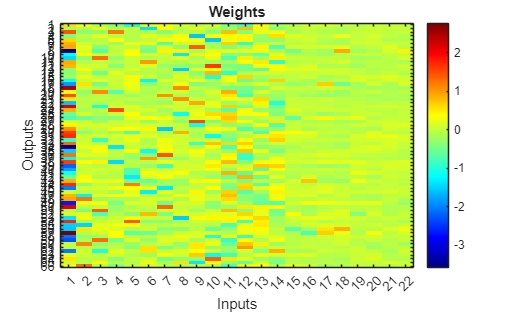

Learnables = Learnables.Value;

weights_input_hidden = extractdata(Learnables{1});

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Weights');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));

Near zero weights

weights_treshold = 0.01 * max(abs(weights_input_hidden(:)))

weights_treshold = single
0.0358

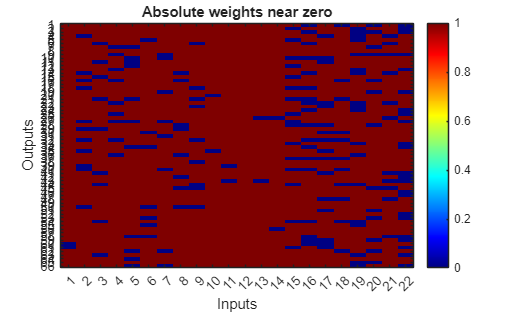

weights_input_hidden(abs(weights_input_hidden) <= weights_treshold) = 0;
weights_input_hidden(abs(weights_input_hidden) > weights_treshold) = 1;

figure;
imagesc(weights_input_hidden);
colorbar;
colormap("jet");
title('Absolute weights near zero');
xlabel('Inputs');
ylabel('Outputs');
xticks(1:size(weights_input_hidden, 2));
yticks(1:size(weights_input_hidden, 1));